# HW5 - ME652 허수민 20203691

close all; clear; clc;

## Problem 1

- Range from vehicle to landmarks ($\rho_{i\;}$)


$$\rho_{i\;} =\sqrt{\;{\left(x_i -x_0 \right)}^{2\;} +{\left(y_i -y_0 \right)}^{2\;} }$$


- Bearing angle from vehicle to landarks ($\beta_{i\;}$)


$$\beta_{i\;} ={\mathrm{tan}}^{-1} \left(\frac{y_i -y_0 }{x_i -x_0 }\right)-\psi \;$$


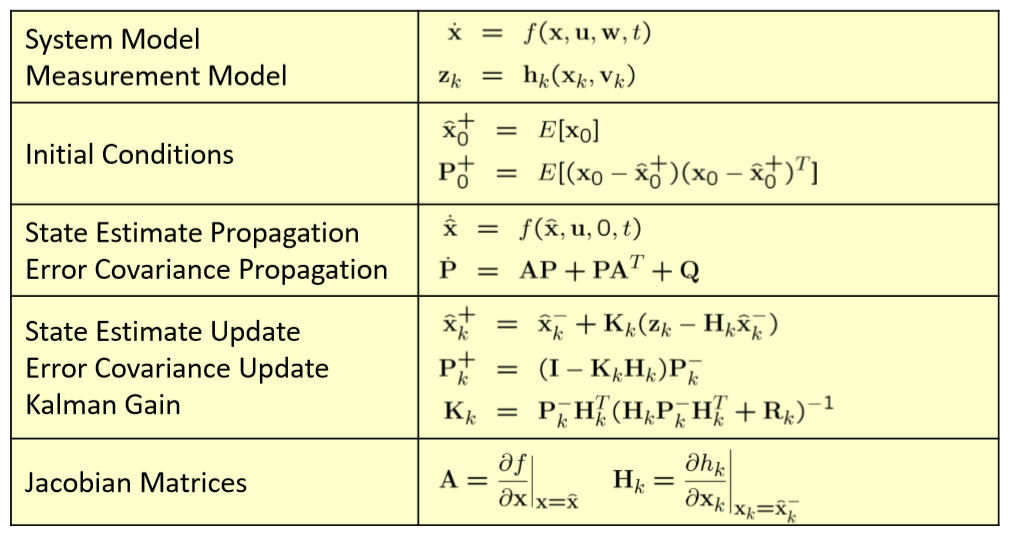

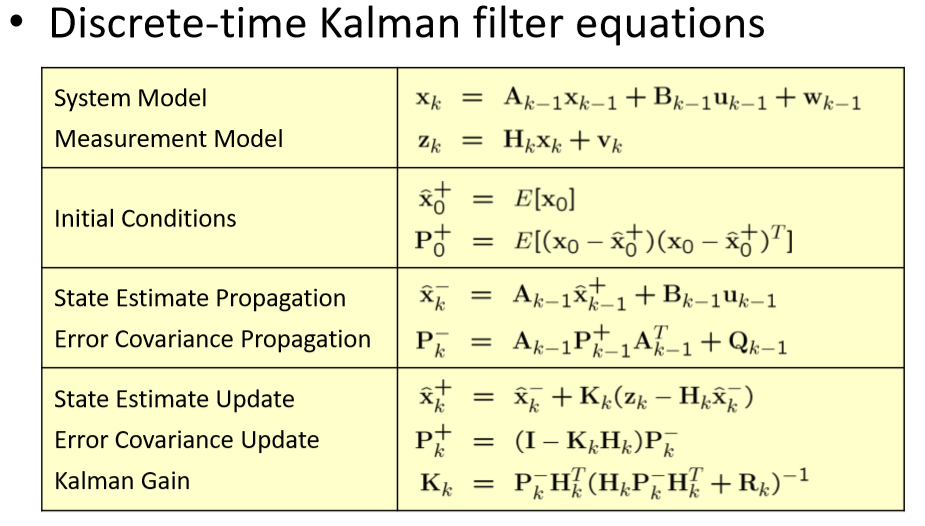

### **jacobian Matrix A**

- 
$$\textrm{size}\left(A\right)=14\;\textrm{by}\;14$$


- 
$$A\left(1,3\right)=\frac{\delta \left\lbrace V\;\cos \left(\psi \right)\right\rbrace }{\delta \left\lbrace \psi \right\rbrace \;}=-V\;\sin \left(\psi \right)$$


- 
$$A\left(2,3\right)=\frac{\delta \left\lbrace V\;\sin \left(\psi \right)\right\rbrace }{\delta \left\lbrace \psi \right\rbrace \;}=V\;\cos \left(\psi \right)$$


- 
$$A\left(1,4\right)=\frac{\delta \left\lbrace V\;\cos \left(\psi \right)\right\rbrace }{\delta \left\lbrace V\right\rbrace \;}=\cos \left(\psi \right)$$


- 
$$A\left(2,4\right)=\frac{\delta \left\lbrace V\;\sin \left(\psi \right)\right\rbrace }{\delta \left\lbrace V\right\rbrace \;}=\sin \left(\psi \right)$$


### **jacobian Matrix H**

- 
$$\textrm{size}\left(H\right)=12\;\textrm{by}\;14$$



$$\begin{array}{l}
\;\textrm{row}:\;\delta \;h\left(x\right)=\left\lbrack \left\lbrack \psi \right\rbrack \left\lbrack V\right\rbrack \left\lbrack \beta_1 \right\rbrack \left\lbrack \rho_1 \right\rbrack \left\lbrack \beta_2 \right\rbrack \left\lbrack \rho_2 \right\rbrack \left\lbrack \beta_3 \right\rbrack \left\lbrack \rho_3 \right\rbrack \left\lbrack \beta_4 \right\rbrack \left\lbrack \rho_4 \right\rbrack \left\lbrack \beta_5 \right\rbrack \left\lbrack \rho_5 \right\rbrack \right\rbrack \\
\textrm{column}:\;\delta \;x=\left\lbrack \left\lbrack x_0 \right\rbrack \left\lbrack y_0 \right\rbrack \left\lbrack \psi \right\rbrack \left\lbrack V\right\rbrack \left\lbrack x_1 \right\rbrack \left\lbrack y_1 \right\rbrack \left\lbrack x_2 \right\rbrack \left\lbrack y_2 \right\rbrack \left\lbrack x_3 \right\rbrack \left\lbrack y_3 \right\rbrack \left\lbrack x_4 \right\rbrack \left\lbrack y_4 \right\rbrack \left\lbrack x_5 \right\rbrack \left\lbrack y_5 \right\rbrack \right\rbrack 
\end{array}$$



$$H=\frac{\delta \;h\left(x\right)}{\delta \;x}{\left|\right.}_{x_k =\hat{x_k \;} }$$


- 
$$\frac{\delta \;\beta_i \;\;}{\delta \;x_0 }=\frac{1}{1+{\left(\frac{y_i -y_0 }{x_i -x_0 }\right)}^2 }\times \frac{y_i -y_0 }{{\left(x_i -x_0 \right)}^2 }=\frac{y_i -y_0 }{{\left(x_i -x_0 \right)}^2 +{\left(y_i -y_0 \right)}^2 }$$


- 
$$\frac{\delta \;\beta_i \;\;}{\delta \;x_i }=\frac{1}{1+{\left(\frac{y_i -y_0 }{x_i -x_0 }\right)}^2 }\times \frac{-\left(y_i -y_0 \right)}{{\left(x_i -x_0 \right)}^2 }=\frac{-\left(y_i -y_0 \right)}{{\left(x_i -x_0 \right)}^2 +{\left(y_i -y_0 \right)}^2 }$$


- 
$$\frac{\delta \;\beta_i \;\;}{\delta \;y_0 }=\frac{1}{1+{\left(\frac{y_i -y_0 }{x_i -x_0 }\right)}^2 }\times \frac{-1}{x_i -x_0 }=\frac{-\left(x_i -x_0 \right)}{{\left(x_i -x_0 \right)}^2 +{\left(y_i -y_0 \right)}^2 }$$


- 
$$\frac{\delta \;\beta_i \;\;}{\delta \;y_i }=\frac{1}{1+{\left(\frac{y_i -y_0 }{x_i -x_0 }\right)}^2 }\times \frac{+1}{x_i -x_0 }=\frac{x_i -x_0 }{{\left(x_i -x_0 \right)}^2 +{\left(y_i -y_0 \right)}^2 }$$


- 
$$\frac{\delta \;\rho_i \;\;}{\delta \;x_0 }=\frac{-\left(x_i -x_0 \right)}{\;\sqrt{\;{\left(x_i -x_0 \right)}^2 +{\left(y_i -y_0 \right)}^2 }}$$


- 
$$\frac{\delta \;\rho_i \;\;}{\delta \;x_i }=\frac{x_i -x_0 }{\;\sqrt{\;{\left(x_i -x_0 \right)}^2 +{\left(y_i -y_0 \right)}^2 }}$$


- 
$$\frac{\delta \;\rho_i \;\;}{\delta \;y_0 }=\frac{-\left(y_i -y_0 \right)}{\;\sqrt{\;{\left(x_i -x_0 \right)}^2 +{\left(y_i -y_0 \right)}^2 }}$$


- 
$$\frac{\delta \;\rho_i \;\;}{\delta \;y_i }=\frac{y_i -y_0 }{\;\sqrt{\;{\left(x_i -x_0 \right)}^2 +{\left(y_i -y_0 \right)}^2 }}$$


### (a) Create your own SLAM code using the given skeleton code (SLAM_skeleton.m). 

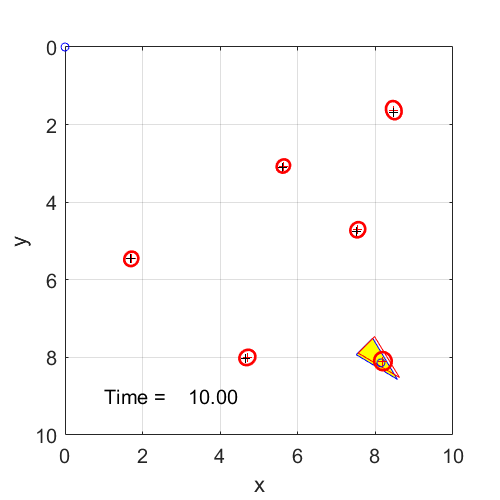

SLAM_skeleton()

### (b) Try different values for the sensor accuracy settings, and then discuss how the performance of SLAM changes. 

The initial noise levels are at 3 degrees for bearing angles and variance of 0.2^2 meters for distance.

We try 3 different noise level multiples: 1.5, 2, and 3. 

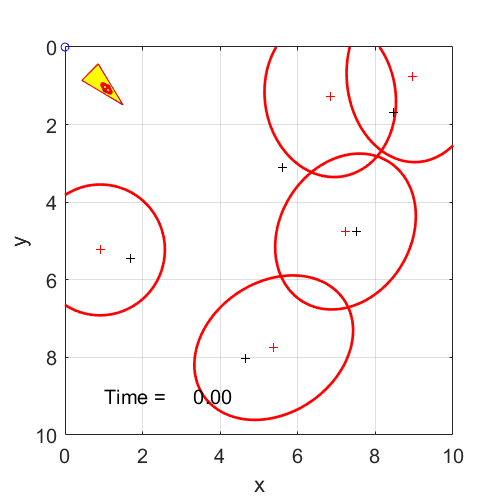

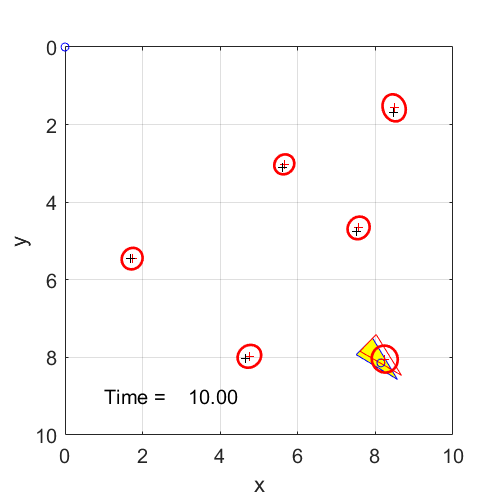

SLAM_skeleton(1.5)

As seen above, with noise levels 1.5 times the original, there seem to be more error than the original diagram.

Now, we proceed with 2 times the noise level. 

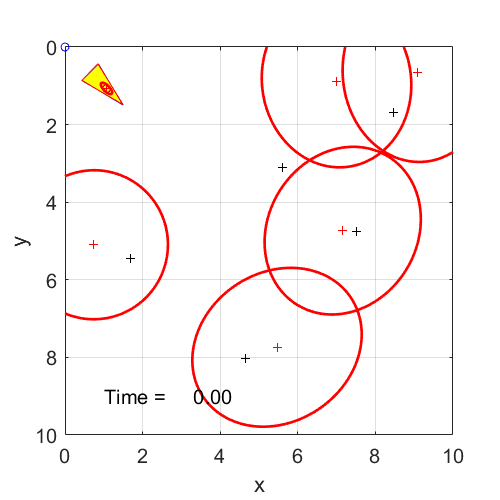

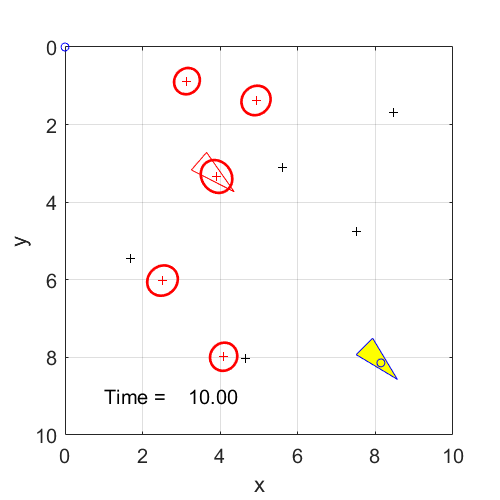

SLAM_skeleton(2)

With noise levels more than 2, the diagram seems to converge to a different position. 

Naturally, with more noise, the error erronenous convergence seems to be worse as shown below.

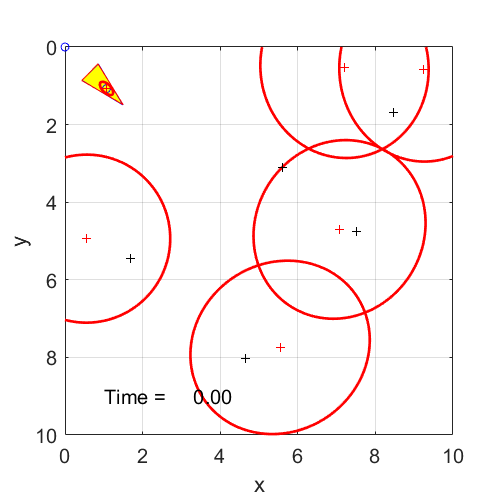

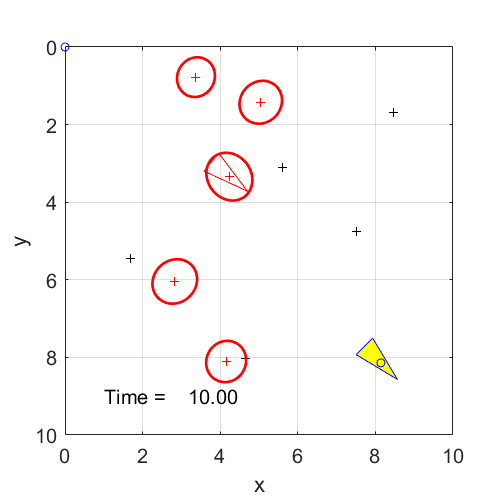

SLAM_skeleton(3)

If we compare the graphs above, we can understand that the a noise level of 2 or more will distort the SLAM algorithm, making it impossible to use SLAM at these error levels.

## Problem 2

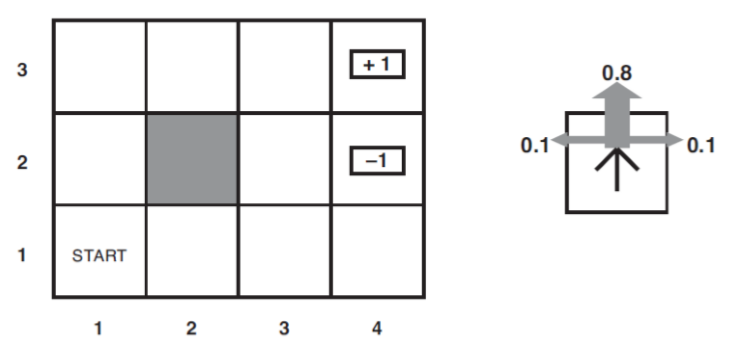

### (a) Complete the MATLAB code for value iteration by filling out two functions “value_iteration” and “extract_policy” in the provided skeleton code (MDP_valueIteration_skeleton.m). Set the immediate reward R = −0.04 for all non-terminal states, and check if your results are correct (see below). 

MDP_ValueIteration_skeleton()


Converged after 26 iterations...

    0.8116    0.8678    0.9178    1.0000
    0.7616         0    0.6603   -1.0000
    0.7053    0.6553    0.6114    0.3879

    "R"    "R"    "R"    "X"
    "U"    "X"    "U"    "X"
    "U"    "L"    "L"    "L"



### (b) Investigate the change of optimal value function and policy by changing the value of reward in nonterminal states and discount factor γ. Then, discuss the results. 

% format of MDP_ValueIteration_skeleton(RValue, GammaValue)
% ex) MDP_ValueIteration_skeleton(-0.04,1)
% R value is -0.04
% Gamma value is 1

First we check the effects of changing the R value, while gamma is 1.

R values of negative, -0.04, -0.1. -0.4

MDP_ValueIteration_skeleton(-0.04,1)


Converged after 26 iterations...

    0.8116    0.8678    0.9178    1.0000
    0.7616         0    0.6603   -1.0000
    0.7053    0.6553    0.6114    0.3879

    "R"    "R"    "R"    "X"
    "U"    "X"    "U"    "X"
    "U"    "L"    "L"    "L"



MDP_ValueIteration_skeleton(-0.1,1)


Converged after 22 iterations...

    0.5700    0.7106    0.8356    1.0000
    0.4450         0    0.5205   -1.0000
    0.3091    0.2223    0.3473    0.0865

    "R"    "R"    "R"    "X"
    "U"    "X"    "U"    "X"
    "U"    "R"    "U"    "L"



MDP_ValueIteration_skeleton(-0.4,1)


Converged after 21 iterations...

   -0.6378   -0.0753    0.4247    1.0000
   -1.1378         0   -0.1781   -1.0000
   -1.6002   -1.2989   -0.7989   -1.2657

    "R"    "R"    "R"    "X"
    "U"    "X"    "U"    "X"
    "U"    "R"    "U"    "L"



The values above, show that the with larger magnitudes of negative rewards will make the process reach its end at a faster pace. Also, the policy in (3,2) changes from left to right, suddenly making immediately closer approaches more prioritized. In more detail, the initial position of a robot will choose to go right towards the reward dispite a negative reward being close. 

Now, we investigate the effects of different gamma values.

gamma values will be 0, 0.2, 0.4, 0.6, 0.8, and 1.

MDP_ValueIteration_skeleton(-0.04,0)


Converged after 1 iterations...

   -0.0400   -0.0400   -0.0400    1.0000
   -0.0400         0   -0.0400   -1.0000
   -0.0400   -0.0400   -0.0400   -0.0400

    "U"    "U"    "R"    "X"
    "U"    "X"    "L"    "X"
    "U"    "U"    "U"    "D"



MDP_ValueIteration_skeleton(-0.04,0.2)


Converged after 7 iterations...

   -0.0453   -0.0214    0.1216    1.0000
   -0.0492         0   -0.0414   -1.0000
   -0.0499   -0.0498   -0.0486   -0.0500

    "R"    "R"    "R"    "X"
    "U"    "X"    "U"    "X"
    "U"    "R"    "U"    "D"



MDP_ValueIteration_skeleton(-0.04,0.4)


Converged after 10 iterations...

   -0.0244    0.0582    0.2923    1.0000
   -0.0520         0    0.0141   -1.0000
   -0.0614   -0.0575   -0.0404   -0.0650

    "R"    "R"    "R"    "X"
    "U"    "X"    "U"    "X"
    "U"    "R"    "U"    "D"



MDP_ValueIteration_skeleton(-0.04,0.6)


Converged after 15 iterations...

    0.0665    0.2146    0.4768    1.0000
   -0.0092         0    0.1371   -1.0000
   -0.0495   -0.0353    0.0186   -0.0845

    "R"    "R"    "R"    "X"
    "U"    "X"    "U"    "X"
    "U"    "R"    "U"    "D"



MDP_ValueIteration_skeleton(-0.04,0.8)


Converged after 17 iterations...

    0.3007    0.4721    0.6821    1.0000
    0.1815         0    0.3441   -1.0000
    0.0911    0.0955    0.1879    0.0003

    "R"    "R"    "R"    "X"
    "U"    "X"    "U"    "X"
    "U"    "R"    "U"    "L"



MDP_ValueIteration_skeleton(-0.04,1)


Converged after 26 iterations...

    0.8116    0.8678    0.9178    1.0000
    0.7616         0    0.6603   -1.0000
    0.7053    0.6553    0.6114    0.3879

    "R"    "R"    "R"    "X"
    "U"    "X"    "U"    "X"
    "U"    "L"    "L"    "L"



Gamma values signify the weight in the Markov Decision Proces; a higher value of gamma means there is going to be more significance in the future rewards and conversely, the lower value of gamma means that there is going to be less significance in the future rewards. Therefore, we can see that the for gamma values of 0, the MDP converges after the 1st iteration, giving the randomly initialized policies as its final policy. Also, we can see that the number of iterations increase with higher gamma values, with the last example requiring 26 iterations to reach its end. 

The policy in the last box at (3,4) seems to be the most resilient to the MDP; we notice it does not change at all until the gamma value is changed to 0.8. This shows how a low gamma value will make the initially made policy more resilient. 

### (c) Implement the MATLAB code for policy-iteration by modifying the code you implemented in (a). 

MDP_PolicyIteration_skeleton


Converged after 6 iterations...

    0.7022    0.8502    0.9139    1.0000
    0.4734         0    0.6486   -1.0000
    0.1140    0.2086    0.4151    0.1303

    "R"    "R"    "R"    "X"
    "U"    "X"    "U"    "X"
    "U"    "R"    "U"    "L"

